# Signal Processing Coursework 

**Signal ID: 69**

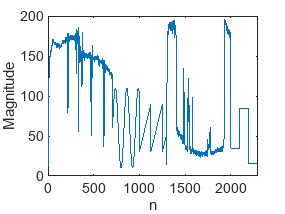

plot(signal);
xlabel("n");
ylabel("Magnitude");

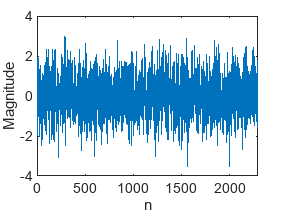

plot(noise);
xlabel("n");
ylabel("Magnitude");

Determine time domain and frequency domain of the original signal. 

### Time domain properties 

Apply difference filter to identify the edges (differences between adjecent values). 

Time domain allows seeing how signal varies accross the time. The in-built diff function calculates differences between adjacent elements of signal. It is clearly visible that there are quite a few edges and many homogenous regions. 

Therefore to identify all edges and divide signal into smaller segments of similar time-domain properties, find function was utilised. 

Important to note, DiffFilter's lenght (number of values) is smaller by one compare to signal's length. It's important to bear that in mind when dividing into segments. 

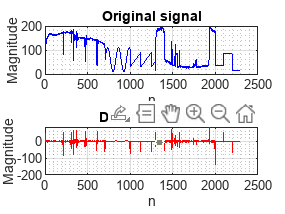

Samples = length(signal); %get number of samples in the signal
DiffFilter = diff(signal); %apply difference filter 
subplot(2,1,1);
plot(signal,"b");
xlabel("n");
ylabel("Magnitude");
grid on;
grid minor;
title("Original signal");
%hold on;
subplot(2,1,2);
plot(DiffFilter, "r");
%hold off;
grid on;
grid minor;
xlabel("n");
ylabel("Magnitude");
title("Difference filter");

%legend("Original signal","DiffFilter signal");

%legend("Position", [0.15008,0.13384,0.25197,0.090599])

#### Edges 

Find function to identify all edges. It looks for all the values within DiffFilter with its absolute values greater than the specified threshold and locates all the spikes. 

**(Double check how to specify the threshold name with lecturer)**

Threshold = 15; %threshold to specify from what values to identify the edges
Spikes = find(abs(DiffFilter)>Threshold);
%plot(Spikes);
%grid on; 
%grid minor;

The first rapid change is observed after the 7th location. Then continually all of the diferrences up to location 11 are higher than 15 indicating rapid changes in the signal and non homogenous region. Therefore the first edge is observed at the 8th location.

Then second edge is at the 11th location, as from there onwards up to location 212th ( just one abnormality) 

Regions: 

1-7 - homogenous 

8-11 - non homogenous 

12 - 217 - homogenous

218 - 221 - non homogenous 

 222 - 305 - homogenous 

306 - 316 - non homogenous? 

317 - 330  - homogenous (double check 331

331 - 337 - non homogenous 

338 -  368 - homogenous 

369 - 378 -  non hmogenous 

379 - 468 - homogenous 

469 - 491 - non homogenous 

492 - 607 - homogenous 

609- 613 (another region not sure what type)

614-704 homogenous 

705 - 998 homogenous (decimal start) 

999 - 1124 homogenous (decimals as well)

1125 - 1250 homogenous (decimals)

1251- 1292 homogenous (decimals)

1293-1299 homogenous 

1300 - 1405 (so tiny spikes there initially as the signal is raising in its amplitude) homogenous?

1406 - 1484 homogenous 

1485 - 1494 non homogenous 

1495 - 